# Numerical Methods for Optimization and Control Theory

## Daniel Kuknyo - Assignment 2

Assigned tasks: 1, 5, 10, 12

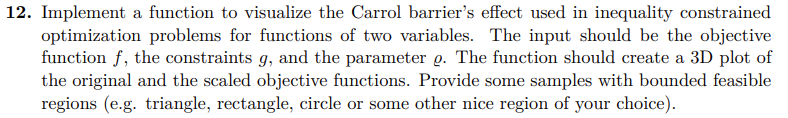

Note: I haven't put this entire code into a function, but kept the visualizations separate to have more control over how it happens. 

## Defining the functions

% Rosenbrock function
clc; clear all;
rr =  [-1.0, 1.2, -0.2, 1.2]; % Recommended region
f = @(x) 100.*(x(2)-x(1).^2).^2+(1-x(1)).^2;

% Equation of a circle
g = @(x,c,r) (x(1)-c(1))^2 + (x(2)-c(2))^2 - r^2;

## Visualizing the original objective function

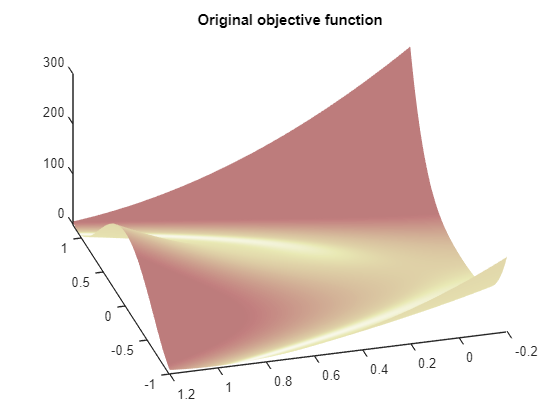

a = rr(1);
b = rr(2);
c = rr(3);
d = rr(4);
res = 256;

X = linspace(a,b,res);
Y = linspace(c,d,res);
[X,Y] = meshgrid(X,Y);
Z = zeros(res,res);

for i=1:res
    for j=1:res
        Z(i,j) = f([X(i,j),Y(i,j)]);
    end
end

figure; hold on;
surfl(X,Y,Z);
colormap("pink");
shading interp;
title("Original objective function");
view([-106 46]);
hold off;

## Visualizing the scaled objective function

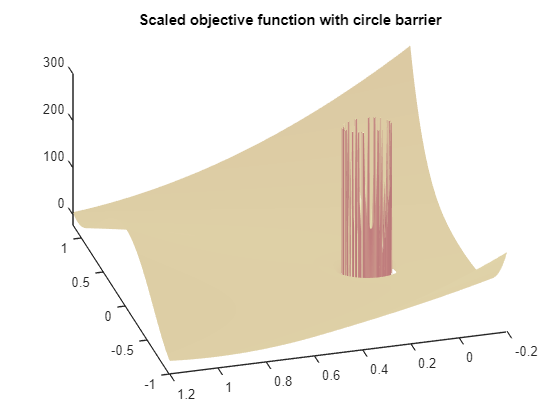

c = [0; 0.2]; % Center of circle 
r = 0.1; % Radius of circle
rho = 10; % Modulation parameter for the barrier

Z = zeros(res,res);
for i=1:res
    for j=1:res
        Z(i,j) = f([X(i,j),Y(i,j)]) + 1/rho * Carrol_barrier(g,[X(i,j),Y(i,j)],c,r);
    end
end

figure; hold on;
surfl(X,Y,Z);
colormap("pink");
shading interp;
title("Scaled objective function with circle barrier");
view([-106 46]);
zlim([-20 300]);
hold off;

## Functions

function gx = Carrol_barrier(g, x, c, r) % Value of the Carrol barrier
    gx = -sum(1./g(x,c,r));
end